%% matlab time
clear all
clc

### p65 (3.1.2) Spatial Velocity

% define fixed body frame {B} Rotate pi/2 align z axis with 1 2 0 translation
TB = SE3(1, 2, 0) * SE3.Rz(pi/2)

 

TB = 
         0        -1         0         1
         1         0         0         2
         0         0         1         0
         0         0         0         1


%define spatial velocity in {B} frame
vb = [0.2 0.3 0 0 0 0.5]'

vb =     0.2000
    0.3000
         0
         0
         0
    0.5000


%%%transform spatial velocity in the world frame
va = TB.velxform * vb

va =    -0.3000
    0.2000
         0
         0
         0
    0.5000


%define fixed body frame {C} tranlation of 0.4 align y compare to B frame
TBC = SE3(0, 0.4, 0)

 

TBC = 
         1         0         0         0
         0         1         0       0.4
         0         0         1         0
         0         0         0         1


% additional frame {C} relative to frame {B}
% compute inverse transform of {C}
TCB = inv(TBC)                             

 

TCB = 
         1         0         0         0
         0         1         0      -0.4
         0         0         1         0
         0         0         0         1


vc = TCB.Ad * vb                           %%%transform spatial velocity in the {C} frame

vc =          0
    0.3000
         0
         0
         0
    0.5000


%% p66 (3.1.3)
%infinitely small rotation can be approximated by the sum of
%a skew-symmetric matrix and identity matrix

rotx(0.001) 

ans =     1.0000         0         0
         0    1.0000   -0.0010
         0    0.0010    1.0000


### **p68 (3.2.1)  Moment of Inertia**

J = [2 -1 0;-1 4 0;0 0 3];                  %%%define inertia matrix of tunbling object

attitude = UnitQuaternion();                %%%initial condition for orientation

w = 0.2*[1 2 2]';                           %%%initial condition for angular velocity

dt = 0.05;

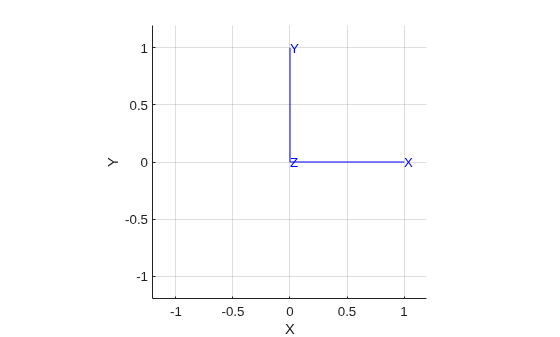

h = attitude.plot();

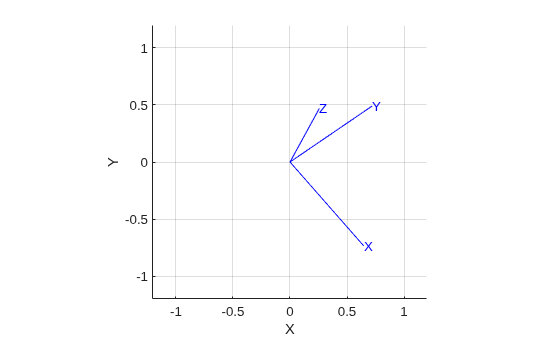

for t=0:dt:10                                                              %%%compute angular acceleration through 
   wd =  -inv(J) * (cross(w, J*w));                                        %%%rectangular integration              
   w = w + wd*dt;  
   attitude = attitude .* UnitQuaternion.omega(wd*dt);
   attitude.plot('handle', h); pause(dt)
end

### **p68 (3.2.2) Wrenches**

WB = [3 4 0 0 0 0]'                         %%%define wrench in frame {B} with force 3 and 4 Nm

WB =      3
     4
     0
     0
     0
     0


WC = TBC.Ad' * WB

WC =     3.0000
    4.0000
         0
         0
         0
    1.2000


### **p71-73 (3.3.1) Trajectory Generation**

clear all
clc

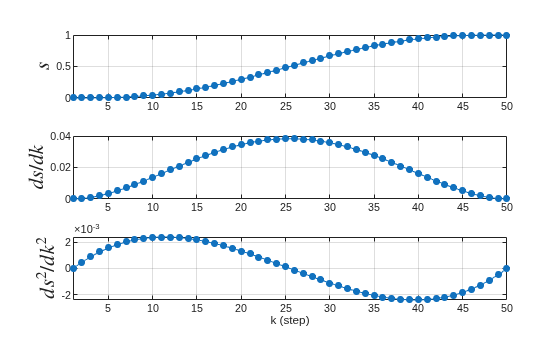

tpoly(0, 1, 50);                            %%%generate a quintic polynomial trajectory

[s,sd,sdd] = tpoly(0, 1, 50)               %%%trajectory-s, velocity-sd and acceleration-sdd

s =          0
    0.0001
    0.0006
    0.0021
    0.0048
    0.0091
    0.0152
    0.0233
    0.0336
    0.0461
    0.0611
    0.0785
    0.0982
    0.1203
    0.1447


sd =          0
    0.0002
    0.0009
    0.0020
    0.0034
    0.0051
    0.0071
    0.0092
    0.0114
    0.0138
    0.0162
    0.0186
    0.0209
    0.0233
    0.0255


sdd =          0
    0.0005
    0.0009
    0.0013
    0.0016
    0.0018
    0.0020
    0.0022
    0.0023
    0.0024
    0.0024
    0.0024
    0.0024
    0.0023
    0.0022


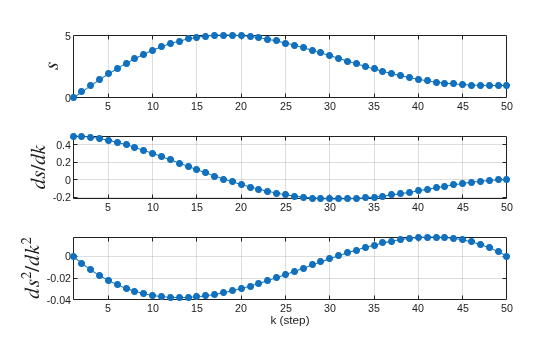

tpoly(0, 1, 50, 0.5, 0);                    %%%define initial velocity (0.5) and final velocity  (0)

mean(sd) / max(sd)                          %%%mean velocity

ans = 0.5231

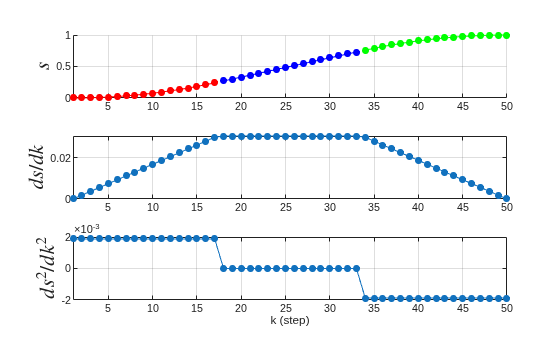

lspb(0, 1, 50);                             % linear segment (constant velocity) with parabolic blends

                                            % constant velocity segment with polynomial segments for acceleration and deceleration
                                            % The trapezoidal trajectory is smooth in velocity, but not in acceleration
                                            % using a constant velocity segment and parabolic blends (a trapezoidal path)

[s,sd,sdd] = lspb(0, 1, 50);                %%%trajectory-s, velocity-sd and acceleration-sdd

max(sd)                                     %%%lspb defined velocity

ans = 0.0306

mean(sd)/max(sd)

ans = 0.6531

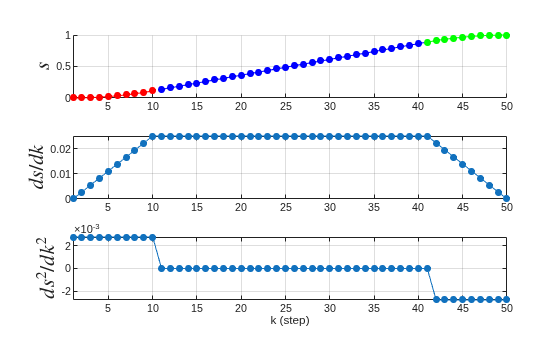

lspb(0, 1, 50, 0.025);
hold on

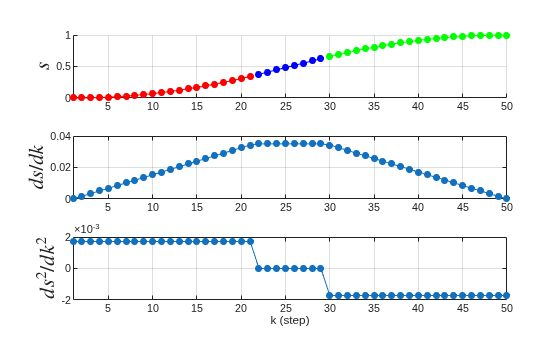

lspb(0, 1, 50, 0.035);


%%%%% We see that as the velocity of the linear segment increases its duration decreases and ultimately its duration would be zero. In fact the velocity cannot be chosen arbitrarily, too high or
%%%%% too low a value for the maximum velocity will result in an infeasible trajectory and the function returns an error


## p73 (3.3.2)  Multi Dimensional Trajectories

clf
%%

q = mtraj(@lspb, [0 2], [1 -1], 50);        %%%generates a multi-segment multi-axis trajectory
                                            %%%based on a matrix of via points

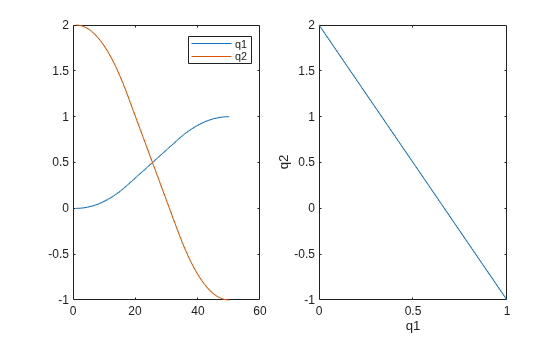

subplot(1,2,1),plot(q), legend('q1','q2')
subplot(1,2,2),plot(q(:,1),q(:,2)), xlabel('q1'), ylabel('q2')

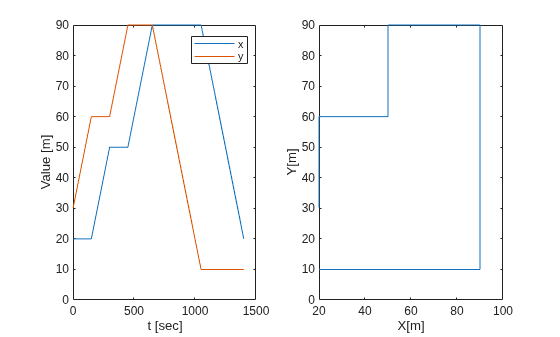

% OR
path=[ 20 30 ;...
       20 60 ;...
       50 60 ;...
       50 90 ;...
       90 90 ;...
       90 10 ;...
       20 10 ;...
    ];
% Generate trajectory
QDMAX=[1,1]; %axis speed limits
Q0= path(1,:); %initial axis coordinates
DT=0.2;
traj = mstraj(path, QDMAX, [], Q0, DT, 0);
subplot(1,2,1),plot(traj), legend('x','y'), xlabel('t [sec]'), ylabel('Value [m]')
subplot(1,2,2),plot(traj(:,1),traj(:,2)), xlabel('X[m]'), ylabel('Y[m]')

%%%% The motion comprises linear motion segments with polynomial blends, like lspb, 
% but here we choose quintic polynomials because they are able to match boundary 
% conditions on position, velocity and acceleration at their start and end points

%% p74-75 (3.3.3)
clf
%%%%
%On a particular motion segment each axis will have a different distance to travel and
% traveling at its maximum speed there will be a minimum time before it can reach its
% goal. The first step in planning a segment is to determine which axis will be the slowest to complete the segment, based on the distance that each axis needs to travel for
% the segment and its maximum achievable velocity. From this the duration of the segment can be computed and then the required velocity of each axis. This ensures that
% all axes reach the next target qk at the same time

%%
via = SO2(30, 'deg') * [-1 1; 1 1; 1 -1; -1 -1]'

via =    -1.3660    0.3660    1.3660   -0.3660
    0.3660    1.3660   -0.3660   -1.3660


q0 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 0.0);   %%%1st arg - via points
                                                                %%%2nd arg - vector of maximum speeds per axis
                                                                %%%3rd arg - vector of duration for each segment
                                                                %%%4rth arg - initial configuration
                                                                %%%5th arg- sample time step
                                                                %%%6th arg - acceleration time

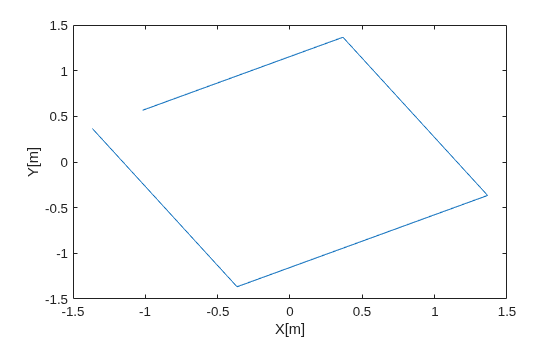

clf
plot(q0(:,1), q0(:,2)), xlabel('X[m]'), ylabel('Y[m]')

%%%increase acceleration time. Trajerctory becomes rounded
q2 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 2);
hold on
size(q2)

ans =     80     2


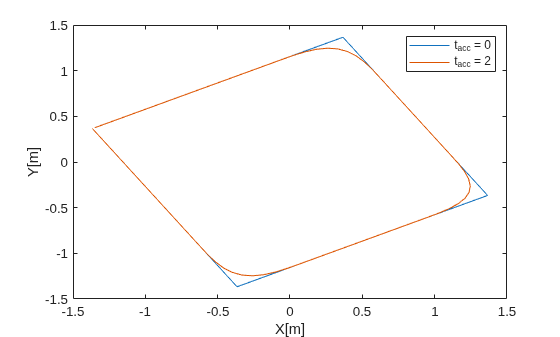

plot(q2(:,1), q2(:,2)), legend('t_{acc} = 0', 't_{acc} = 2')

%% Keep in mind that this function simply interpolates pose represented as a vector.
%%
[numrows(q0) numrows(q2)]

ans =     28    80


**Assignt Time Durations per Segment**

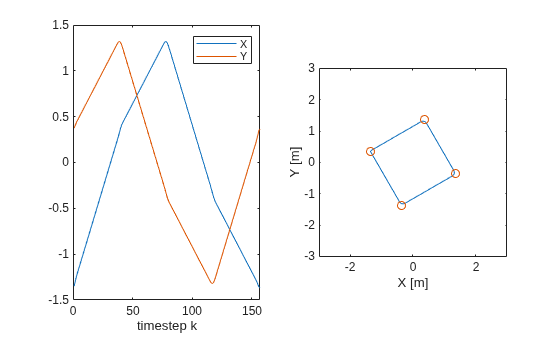

clc
clear all
clf

via = SO2(30, 'deg') * [-1 1; 1 1; 1 -1; -1 -1]';
QD_MAX = []; % cannot specify both max vel and durations of each segment
TIME_DURS = [8,8,8,8];
%TIME_DURS = [2,2,2,2];
TACC = 1.0;
traj = mstraj(via(:,[2 3 4 1])', QD_MAX, TIME_DURS, via(:,1)', 0.2, TACC);

subplot(1,2,1)
plot(traj(:,1)), hold on, plot(traj(:,2)),
legend('X', 'Y'), xlabel('timestep k')

subplot(1,2,2)
plot(traj(:,1),traj(:,2)), axis equal, hold on, plot(via(1,:),via(2,:), 'o')
xlabel('X [m]'), ylabel('Y [m]'), xlim([-3,3]), ylim([-3, 3])

### ** p76 (3.3.4) Interpolation of Orientation**

clf
R0 = SO3.Rz(-1) * SO3.Ry(-1)                                   %%%define rotation R0

 

R0 = 
    0.2919    0.8415   -0.4546
   -0.4546    0.5403    0.7081
    0.8415         0    0.5403


R1 = SO3.Rz(1) * SO3.Ry(1)                                    %%%define rotation R1

 

R1 = 
    0.2919   -0.8415    0.4546
    0.4546    0.5403    0.7081
   -0.8415         0    0.5403


rpy0 = R0.torpy(); rpy1 = R1.torpy();                           %%%calculate rpy angles for R0 and R1

rpy = mtraj(@tpoly, rpy0, rpy1, 50);                            %%%create 50 steps trajectory between rpy0 and rpy1

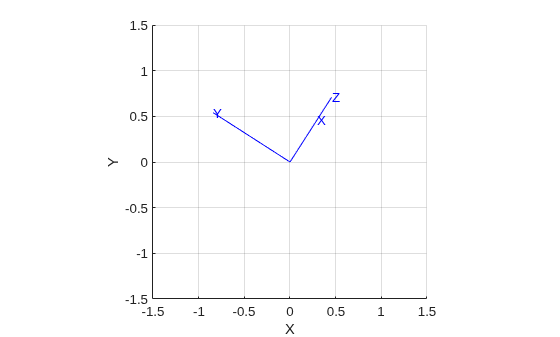

clf
SO3.rpy( rpy ).animate;                                         %%%visualize animation

q0 = R0. UnitQuaternion;                                        %%%define quaternion q0

q1 = R1.UnitQuaternion;                                         %%%define quaternion q1

q = interp(q0, q1, 50);                                         %%%interpolate q0 and q1

about(q)

q [UnitQuaternion] : 1x50 (1.6 kB)


clf
q.animate()

### **p76 (3.3.4.1) Direction of Rotation**

q0 = UnitQuaternion.Rz(-2);                                     %%%create rotation around z axis of -2 rads

q1 = UnitQuaternion.Rz(2);                                      %%%create rotation around z axis of +2 rads

q = interp(q0, q1, 50);                                         %%%interpolate

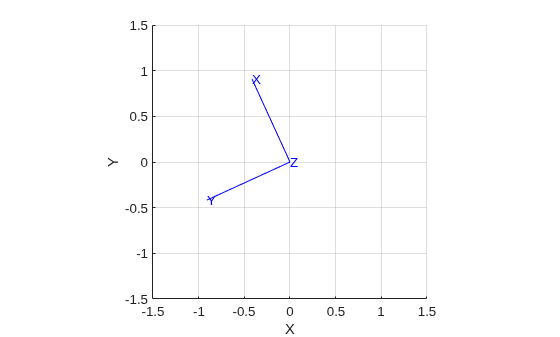

q.animate()

q = interp(q0, q1, 50, 'shortest');                             %%%select shortest path

q.animate()

**p77 (3.3.6) **

clear all
clc
clf

T0 = SE3([0.4, 0.2, 0]) * SE3.rpy(0, 0, 3);                     %%%define intial pose T0

T1 = SE3([-0.4, -0.2, 0.3]) * SE3.rpy(-pi/4, pi/4, -pi/2);      %%%define final pose T1

interp(T0, T1, 0.5)                                             %%%interpolate

 

ans = 
    0.0975   -0.7020    0.7055         0
    0.7020    0.5510    0.4512         0
   -0.7055    0.4512    0.5465      0.15
         0         0         0         1


Ts = interp(T0, T1, 50);

about(Ts)

Ts [SE3] : 1x50 (6.4 kB)


Ts(1)

 

ans = 
   -0.9900   -0.1411         0       0.4
    0.1411   -0.9900         0       0.2
         0         0         1         0
         0         0         0         1


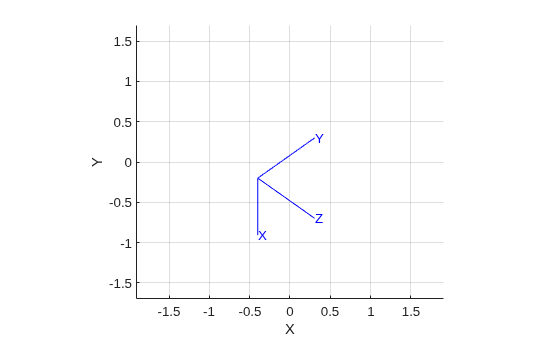

Ts.animate

P = Ts.transl;

about(P)

P [double] : 50x3 (1.2 kB)


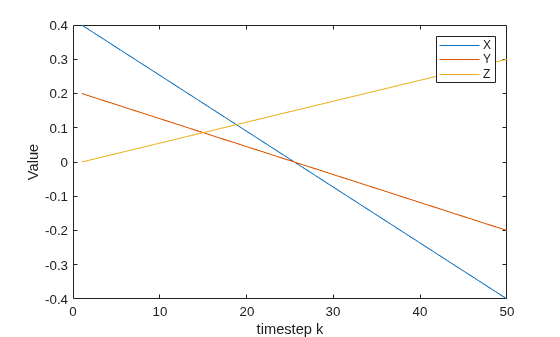

plot(P), legend('X','Y', 'Z'), xlabel('timestep k'), ylabel('Value')

rpy = Ts. torpy;                                                %%%extract rpy angles of trajectory

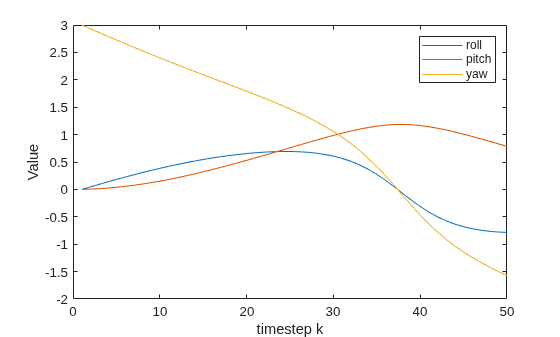

plot(rpy); legend('roll','pitch', 'yaw'), xlabel('timestep k'), ylabel('Value')

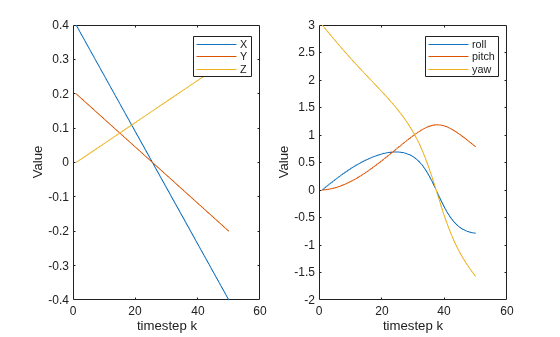

figure.Position = [100 100 1000 400];
subplot(1,2,1), plot(P), legend('X','Y', 'Z'), xlabel('timestep k'), ylabel('Value')
subplot(1,2,2),plot(rpy); legend('roll','pitch', 'yaw'), xlabel('timestep k'), ylabel('Value')

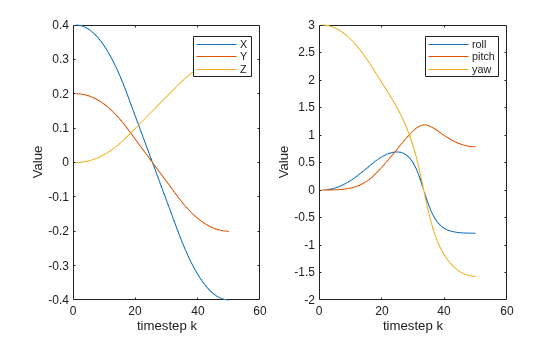

Ts = T0. interp(T1, lspb(0,1, 50) );                            %%%the coordinate frame now accelerates to a
                                                                %%%constant speed along the path and then decelerates
                                                                %%%and this is reflected in smoother curve for the trajectory
clf
rpy = Ts. torpy; 
P = Ts.transl;

figure.Position = [100 100 1000 400];

subplot(1,2,1), plot(P), legend('X','Y', 'Z'), xlabel('timestep k'), ylabel('Value')
subplot(1,2,2),plot(rpy); legend('roll','pitch', 'yaw'), xlabel('timestep k'), ylabel('Value')

Ts = ctraj(T0, T1, 50);                                         %%%compact form of the above
about(Ts)

Ts [SE3] : 1x50 (6.4 kB)
